meanTemp = (-5:20)';
month = [1:12];
temp1 = meanTemp + 12*sin((2*pi/12)*(month-5))

temp1 =   -15.3923  -17.0000  -15.3923  -11.0000   -5.0000    1.0000    5.3923    7.0000    5.3923    1.0000   -5.0000  -11.0000
  -14.3923  -16.0000  -14.3923  -10.0000   -4.0000    2.0000    6.3923    8.0000    6.3923    2.0000   -4.0000  -10.0000
  -13.3923  -15.0000  -13.3923   -9.0000   -3.0000    3.0000    7.3923    9.0000    7.3923    3.0000   -3.0000   -9.0000
  -12.3923  -14.0000  -12.3923   -8.0000   -2.0000    4.0000    8.3923   10.0000    8.3923    4.0000   -2.0000   -8.0000
  -11.3923  -13.0000  -11.3923   -7.0000   -1.0000    5.0000    9.3923   11.0000    9.3923    5.0000   -1.0000   -7.0000
  -10.3923  -12.0000  -10.3923   -6.0000         0    6.0000   10.3923   12.0000   10.3923    6.0000    0.0000   -6.0000
   -9.3923  -11.0000   -9.3923   -5.0000    1.0000    7.0000   11.3923   13.0000   11.3923    7.0000    1.0000   -5.0000
   -8.3923  -10.0000   -8.3923   -4.0000    2.0000    8.0000   12.3923   14.0000   12.3923    8.0000    2.0000   -4.0000
   -7.3923   -9.0000   -


temp2 = [-10:1:20];
A = @(temp2) 200 .* (12 - temp2);
cost = @(temp2) 1000 + max(A(temp2), 0);
y = cost(temp2);

f_cost = sum(cost(temp1))

f_cost = 1.0e+05 *

    1.0344    1.1180    1.0344    0.8120    0.5660    0.3920    0.3105    0.2900    0.3105    0.3920    0.5660    0.8120


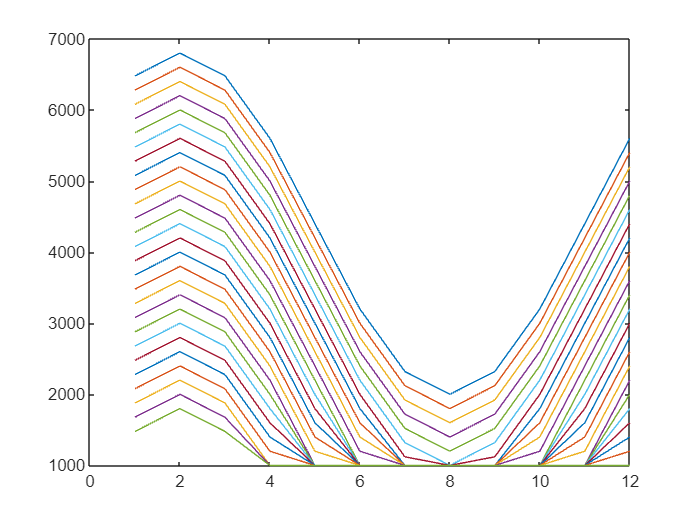

y2 = cost(temp1);
plot(month, y2)

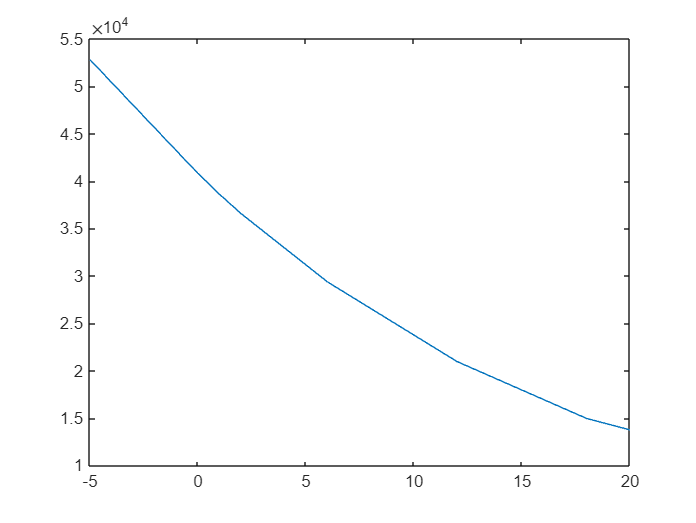


plot(meanTemp, sum(y2,2))

l = [10;20;30]

l =     10
    20
    30


A = 0.0005^2*pi

A = 7.8540e-07

p = [1.59, 1.68, 2.44, 2.82, 10] * 10^-8

p = 1.0e-07 *

    0.1590    0.1680    0.2440    0.2820    1.0000


R = (l.*p)/A

R =     0.2024    0.2139    0.3107    0.3591    1.2732
    0.4049    0.4278    0.6213    0.7181    2.5465
    0.6073    0.6417    0.9320    1.0772    3.8197



I = [10, 100]

I =     10   100


I = reshape(I, [1,1,length(I)])

I = I(:,:,1) =

    10


I(:,:,2) =

   100


P = R.*I.^2

P = P(:,:,1) =

   20.2445   21.3904   31.0670   35.9054  127.3240
   40.4890   42.7808   62.1341   71.8107  254.6479
   60.7335   64.1713   93.2011  107.7161  381.9719


P(:,:,2) =

   1.0e+04 *

    0.2024    0.2139    0.3107    0.3591    1.2732
    0.4049    0.4278    0.6213    0.7181    2.5465
    0.6073    0.6417    0.9320    1.0772    3.8197
